# Stima Giunto 1 su SCARA. 

Modello giunto 1

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi
addpath(['..',filesep,'modelli']) %aggiunge al path la cartella modelli (che deve essere nella cartella superiore)
addpath(['..',filesep,'progetto0']) %aggiunge al path la cartella progetto0 (che deve essere nella cartella superiore)

system=ElasticRoboticSystem();
st=system.getSamplingPeriod;

cs=ControlledSystemScara(system,'progetto0');

ctrl=SimpleScaraController(cs.getSamplingPeriod);
cs.setController(ctrl);

## Identificazione

Definisco segnale di identificazione

#### Portante

omega_portante=0.1;
ampiezza_portante=30;
T_portante=2*pi/omega_portante;
t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

#### Segnale eccitante

w0=1; %rad/s
w1=1000; %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');

ampliezza_identificazione=80;

sommo

exciting_signal=zeros(length(t),system.getInputNumber);
exciting_signal(:,1)=portante+ control_action_identificazione*ampliezza_identificazione;


Simulo il sistema

cs.initialize % reinizializza la simulatione

cs.setRestTime(1); % attendi di stabilizzarti
cs.moveTo([0 0]); % cambia punto di lavoro

measure=system.computeOutput;

reference=zeros(length(t),6); % 2*(pos,vel,acc)
reference(:,1)=measure(1);
reference(:,2)=measure(2);

for idx=1:length(t)
        % step: simulo il sisteme in anello chiuso
        [process_output(idx,:),control_action(idx,:),t(idx,1)]=cs.step(reference(idx,:)',exciting_signal(idx,:)');  
        % ingresso 1: riferimento
        % ingresso 2: segnale a valle del controllore
end

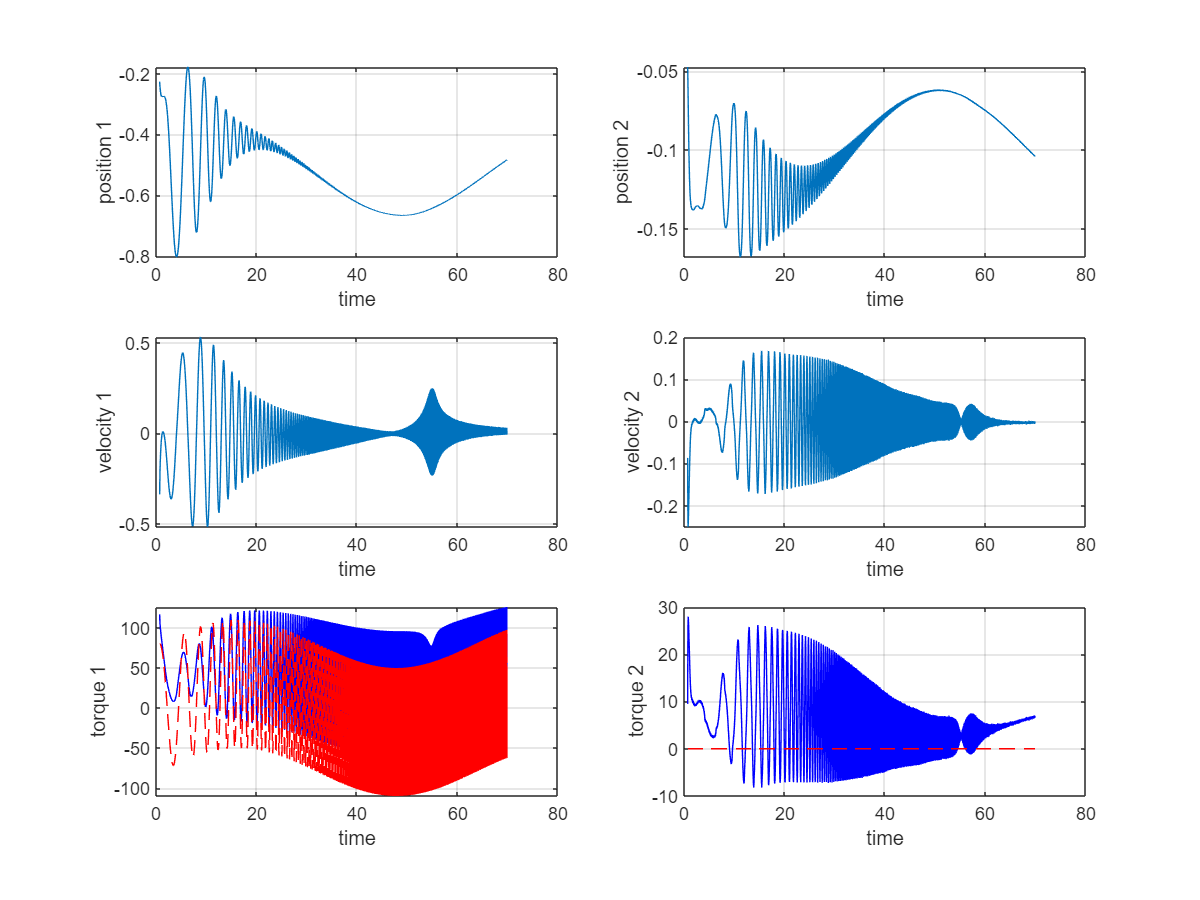

figure(1)
subplot(3,2,1)
plot(t,process_output(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(3,2,3)
plot(t,process_output(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(3,2,5)
plot(t,control_action(:,1),'-b',t,exciting_signal(:,1),'--r')
xlabel('time')
ylabel('torque 1')
grid on

subplot(3,2,2)
plot(t,process_output(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(3,2,4)
plot(t,process_output(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(3,2,6)
plot(t,control_action(:,2),'-b',t,exciting_signal(:,2),'--r')
xlabel('time')
ylabel('torque 2')
grid on

Salvo i risultati

figure

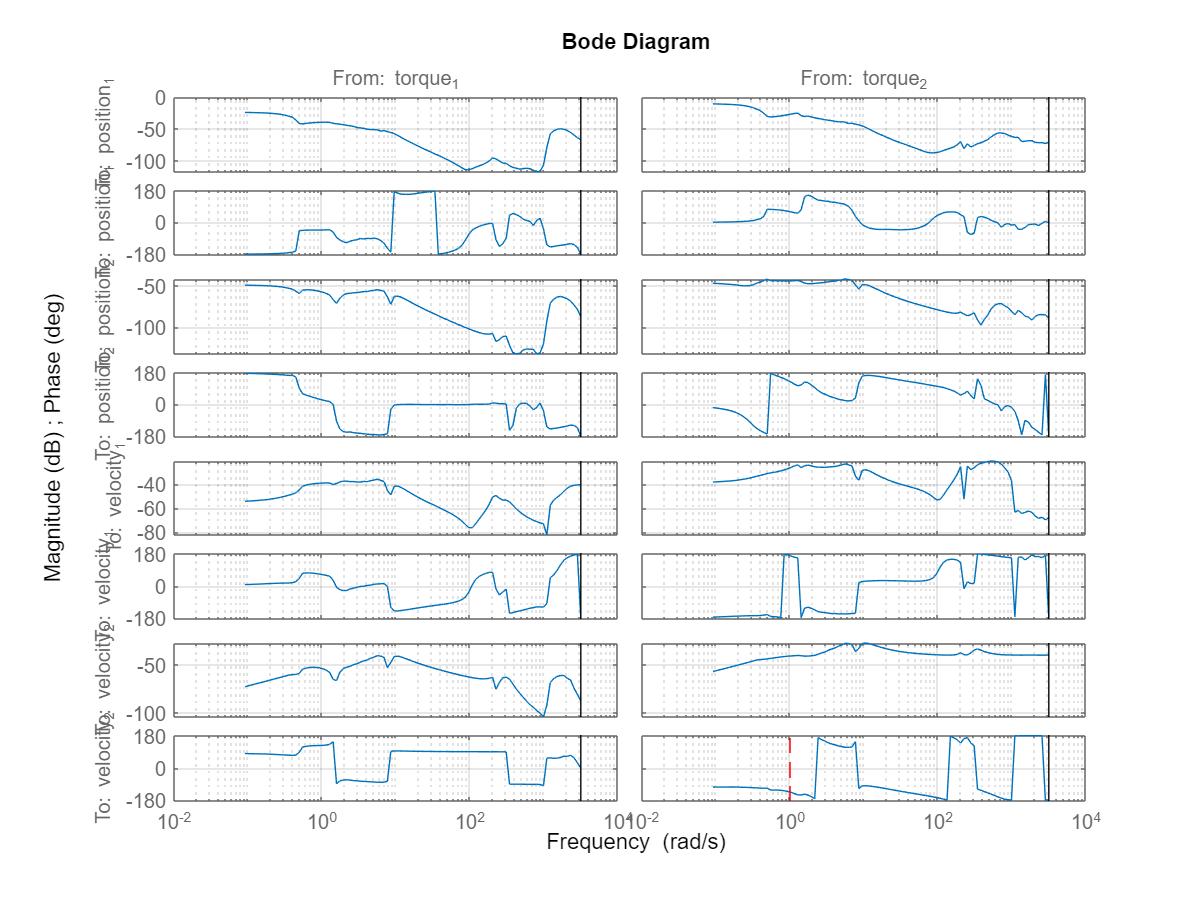

experiment=iddata(process_output,control_action,st);
experiment.InputName=system.getInputName;
experiment.OutputName=system.getOutputName;
experiment_freqresp = spafdr(experiment);

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(experiment_freqresp, bode_opts);
grid on
hold on
hold on
plot(w0*[1 1],ylim,'--r')
hold off
grid on